# Replicate a molecule

First import a molecule...

atom=import_atom('1xMMT.gro');

Found .gro file
.gro file imported
Elapsed time is 0.137017 seconds.


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 40

Atom_types = 1×4 cell array
    'Al'    'H'    'O'    'Si'

Atom_numbers =      4     4    24     8

Box_dim =    5.198000000000000   9.015000000000001  10.000000000000000

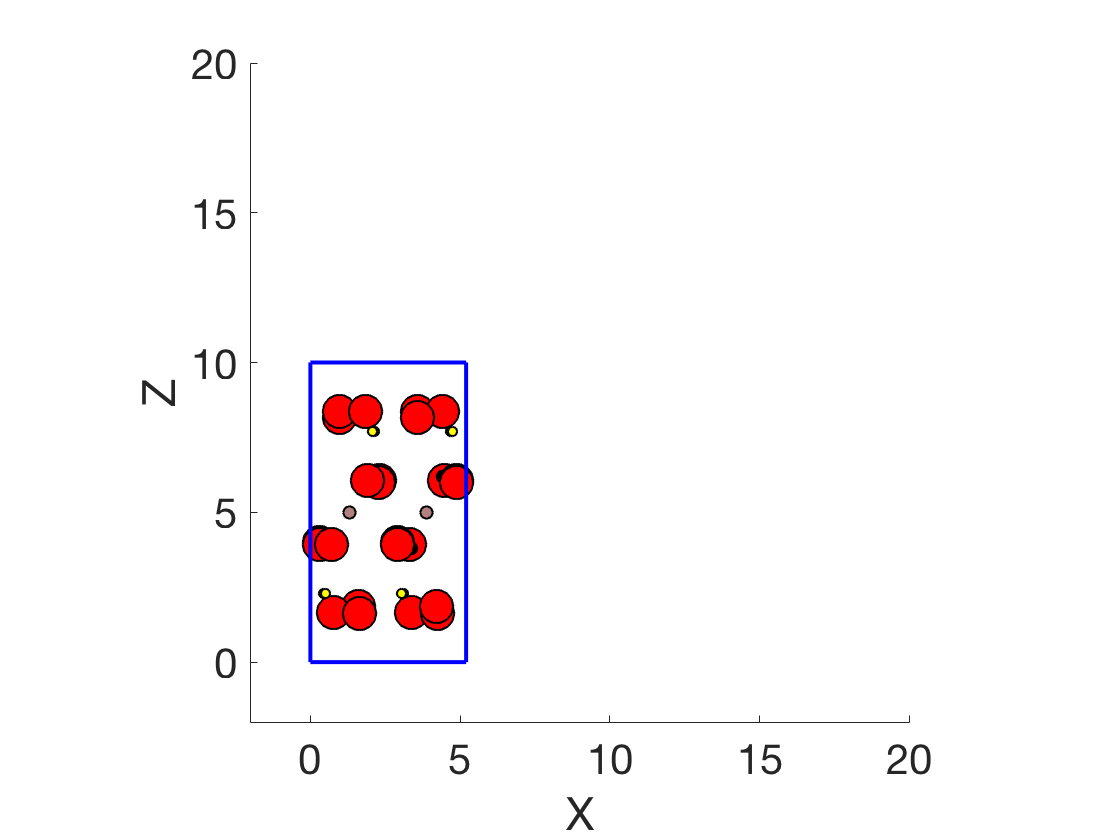

plot_atom(atom,Box_dim); hold off;

%vmd(atom,Box_dim)

Then replicate it like this...

atom_replicated=replicate_atom(atom,Box_dim,[6 4 1]); % This will also replicate Box_dim

x - dim


ans =    240

y - dim


ans =    960

z - dim


ans =    960

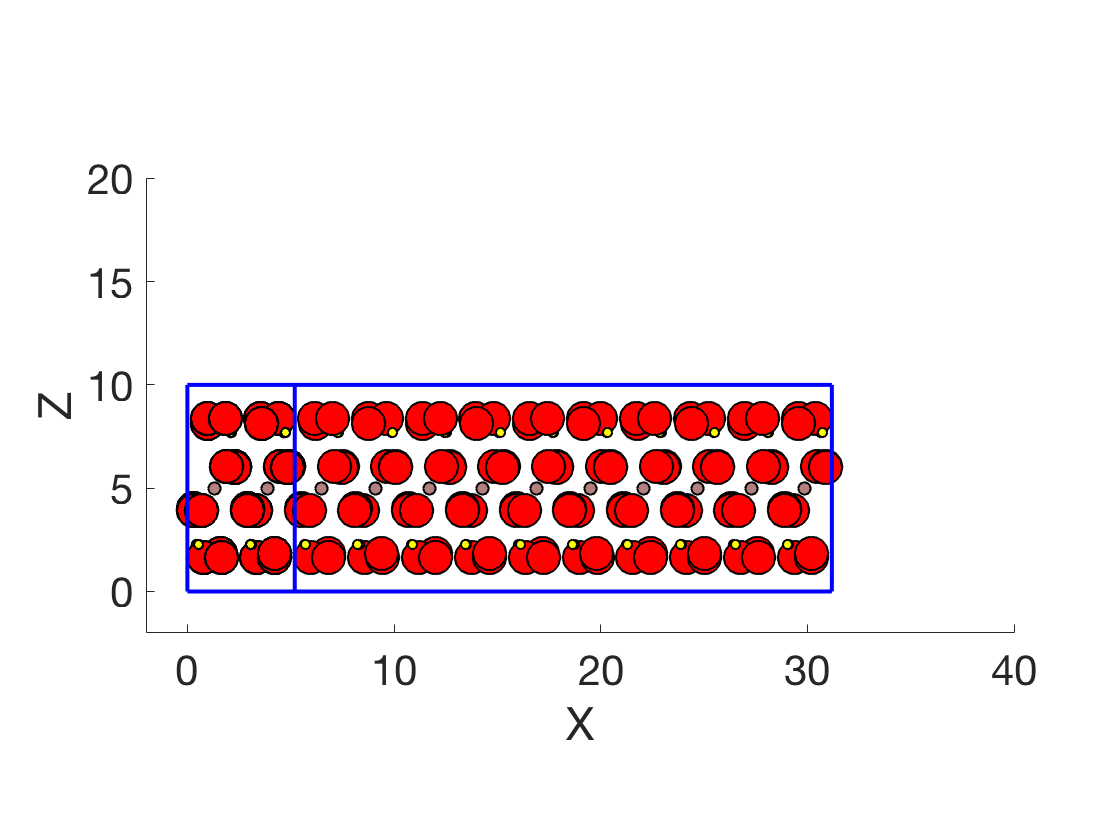

plot_atom(atom_replicated,Box_dim); hold off;

%vmd(atom,Box_dim)

There is also an option to replicate the molecule along the x/y/z directions in a different order, like this

atom=import_atom('1xMMT.gro');
atom_replicated_yxz=replicate_atom(atom,Box_dim,[6 4 1],'yxz'); % This will also replicate Box_dim

y - dim


ans = 160

x - dim


ans = 960

z - dim


ans = 960

plot_atom(atom_replicated_yxz,Box_dim);

%vmd(atom,Box_dim)